# Basics of Surrogate Model Creation

## Goals

- **Outline Process:** Explain the fundamental steps involved in creating surrogate models of physics-based models.

- **Highlight Key Benefits:** Emphasize the advantages of using surrogate models, particularly their ability to predict system behavior faster than traditional physics-based models without compromising accuracy.

- **Illustrate Performance Evaluation:** Assess surrogate model performance, focusing on error analysis and comparisons with physics-based models.

The article references a MATLAB executable notebook found here.

## High-Level Highlights

Surrogate models drastically increase the utility of physics-based models and provide a blazing-fast engine for analysis, optimization, and digital twin applications. The tables below showcase a key feature of surrogate models: they obtain answers that are nearly identical to physics-based models but in a fraction of the time.

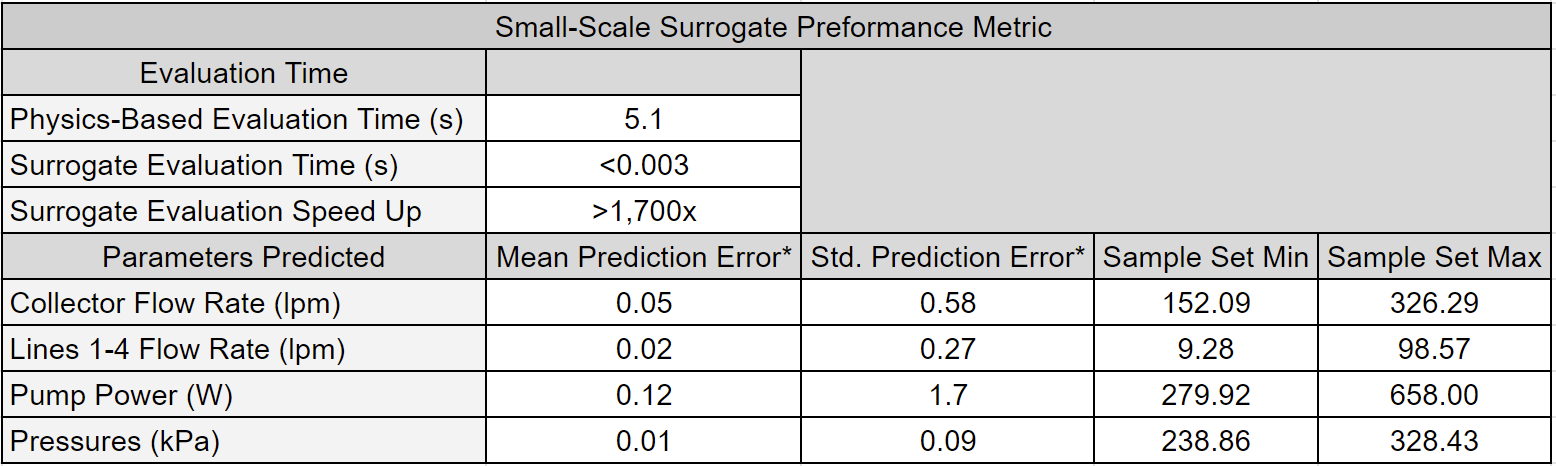

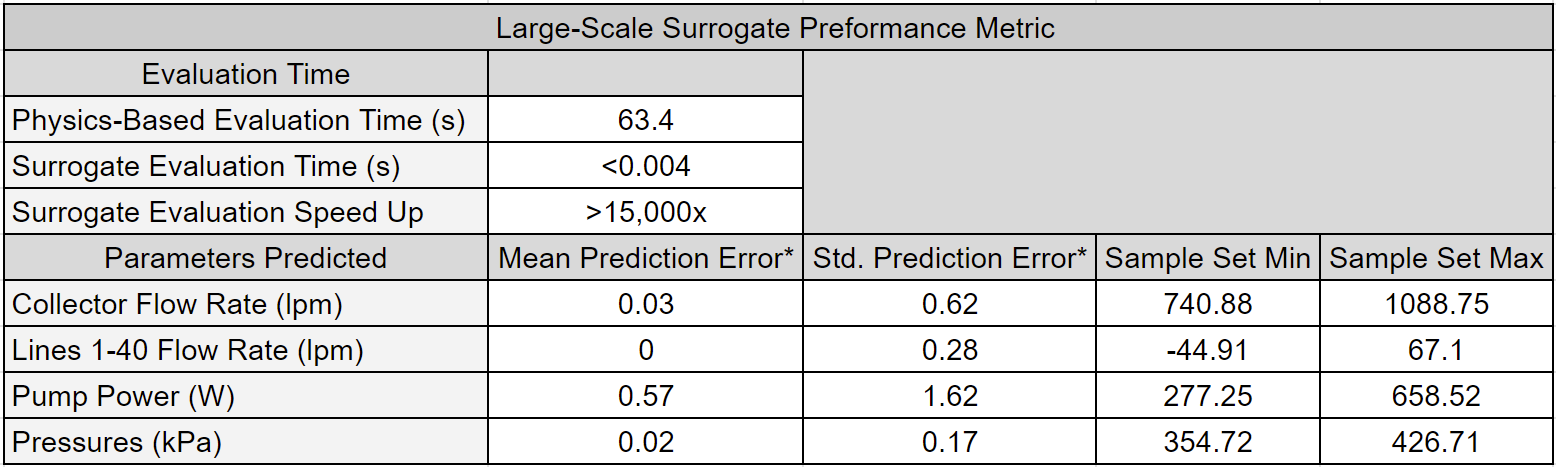

Other articles will explore how surrogate models are leveraged to unlock novel workflows.

## Physics-Based Model: Water Pumping Network Model

### Model Selection

In this article, we employ two water-pumping network models to illustrate the process of surrogate model creation. We begin with a small-scale model featuring four pumps to guide readers through the essential steps. Additionally, we introduce a larger-scale model with 40 pumps to highlight the scalability of the approach. It's important to note that our focus is solely on steady-state solutions.

### Complex Dynamics of Water Pumping Networks

Water pumping networks are complex systems that exhibit coupled behavior between pumps. Simulators obtain valid solutions by resolving network pressure balance equations with iterative numerical solvers. Adjusting a single pump setting can reverberate throughout the entire network, impacting pressure and flow rate. Furthermore, the network model incorporates centrifugal pump models, capturing the intricate relationship between operating speed, flow rate, and brake power with complex pump curves. 

Typically, water pumping networks are finely balanced and have additional components such as check valves to prevent backflow (water flowing back to the source). In the following, backflow is allowed since the scope of this article is to explain the basics of surrogate model creation. Therefore, some of the data collected from the physics-based model may contain undesired system behavior, but regardless, the surrogate model will accurately predict the simulated system's behavior. A subject matter expert may carefully select the sampling bounds to prevent undesired operating conditions. Nevertheless, subsequent articles will address check valves and backflow. 

### Modular Structure of the Models

The models follow a modular structure comprised of interconnected subsystems. Each subsystem consists of a collection of lines. Each line includes a source, a pipe connecting the source to a pump, the pump itself, sensors to capture pump power, pressure, and flow rate at the pump's outlet, and a pipe leading the flow out of the line. A collection of lines are connected via an ideal junction to create a subsystem. Pipes connect these subsystems, and a collector node is a sink for the entire network. We provide simulink models for both small and large-scale systems. The lengths and elevation gains of the pipes are considered static during surrogate model creation, as they remain constant when generating samples. However, the provided sampling scripts and models allow for easy parameter configuration. Each centrifugal pump model utilizes the pump curves of the Ebara EVMS 1 10/0.55 Vertical Multistage Pump.

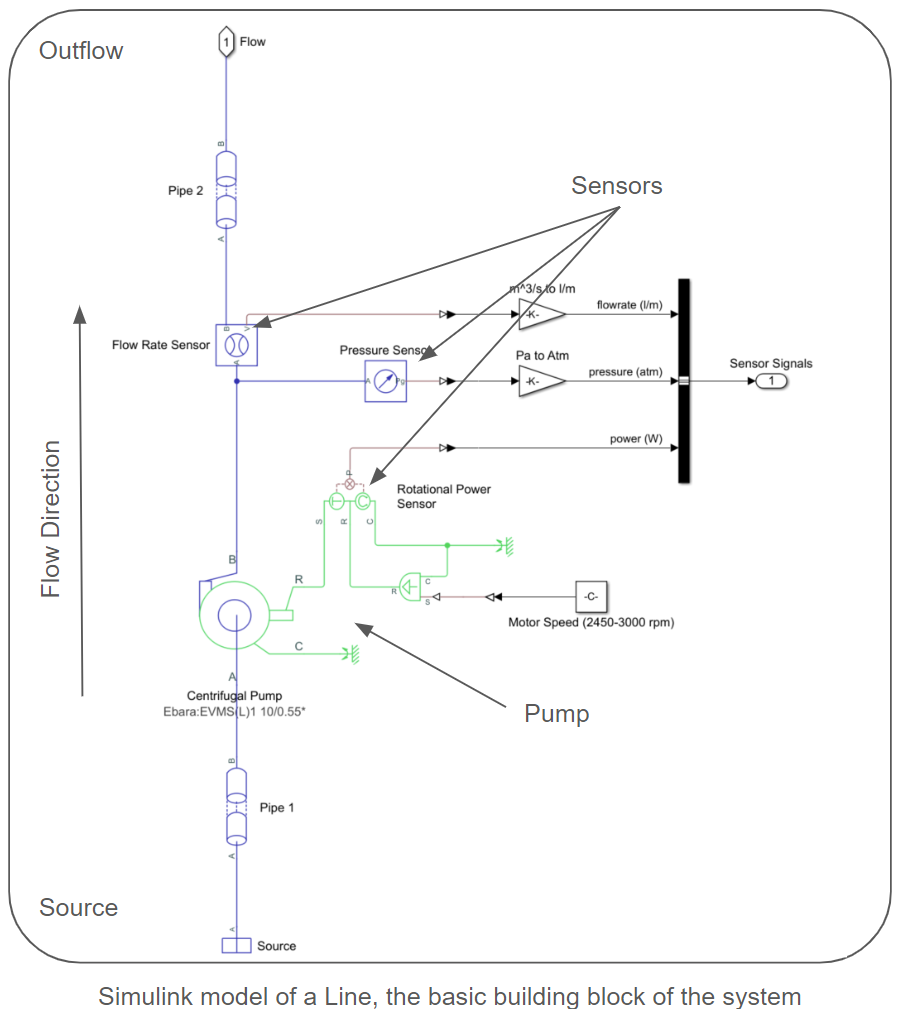

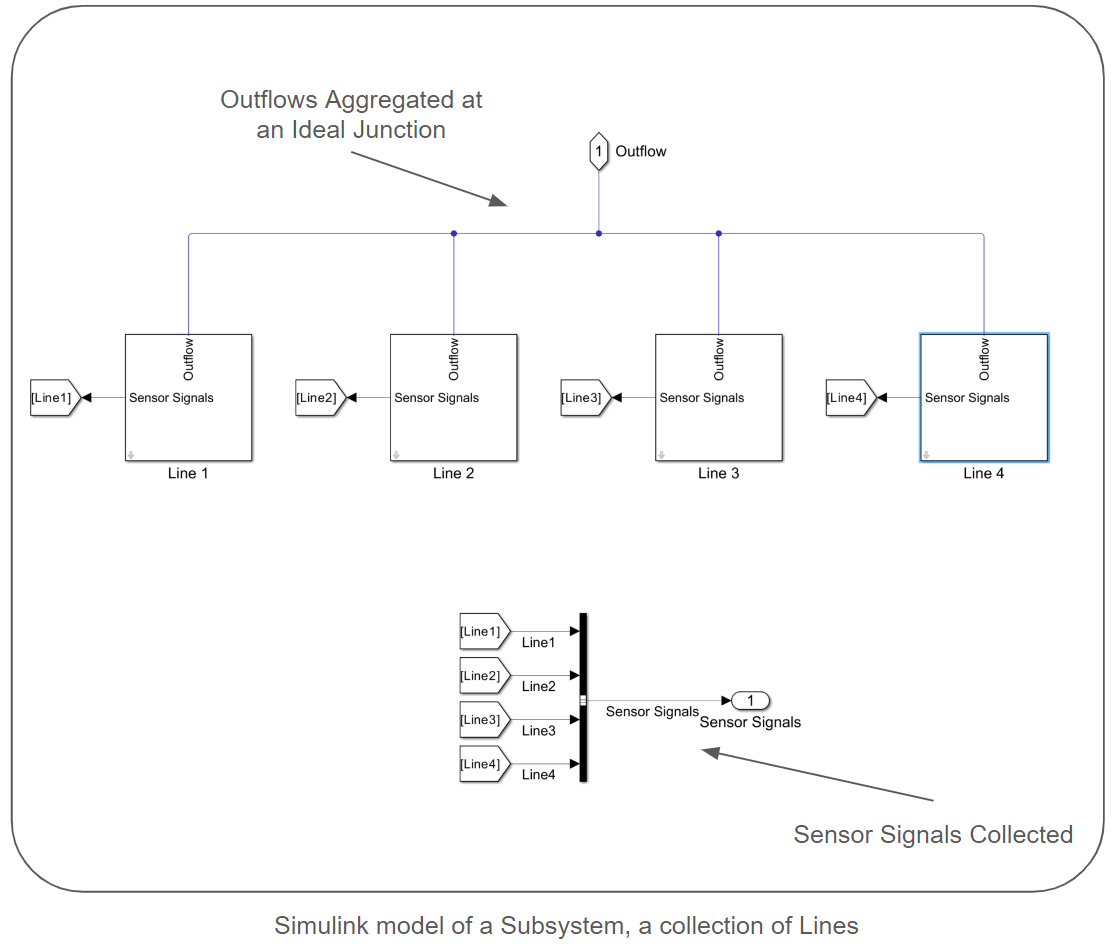

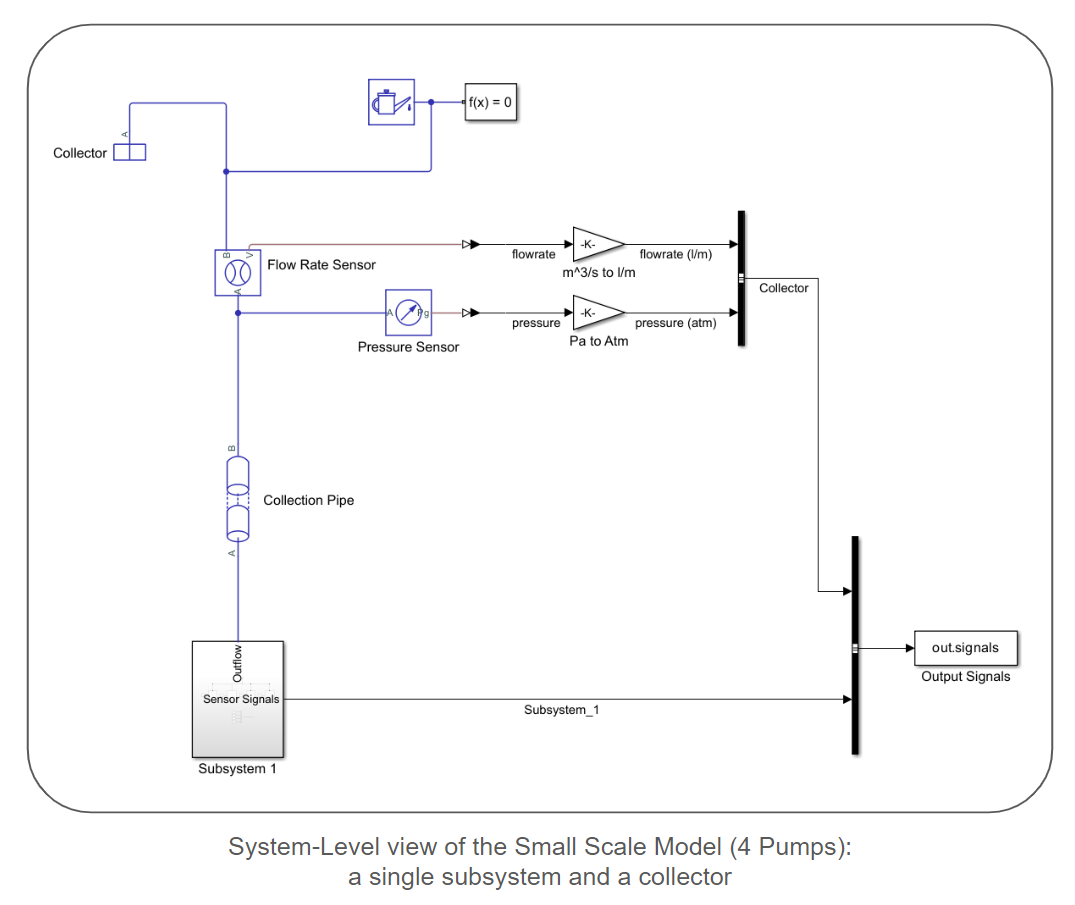

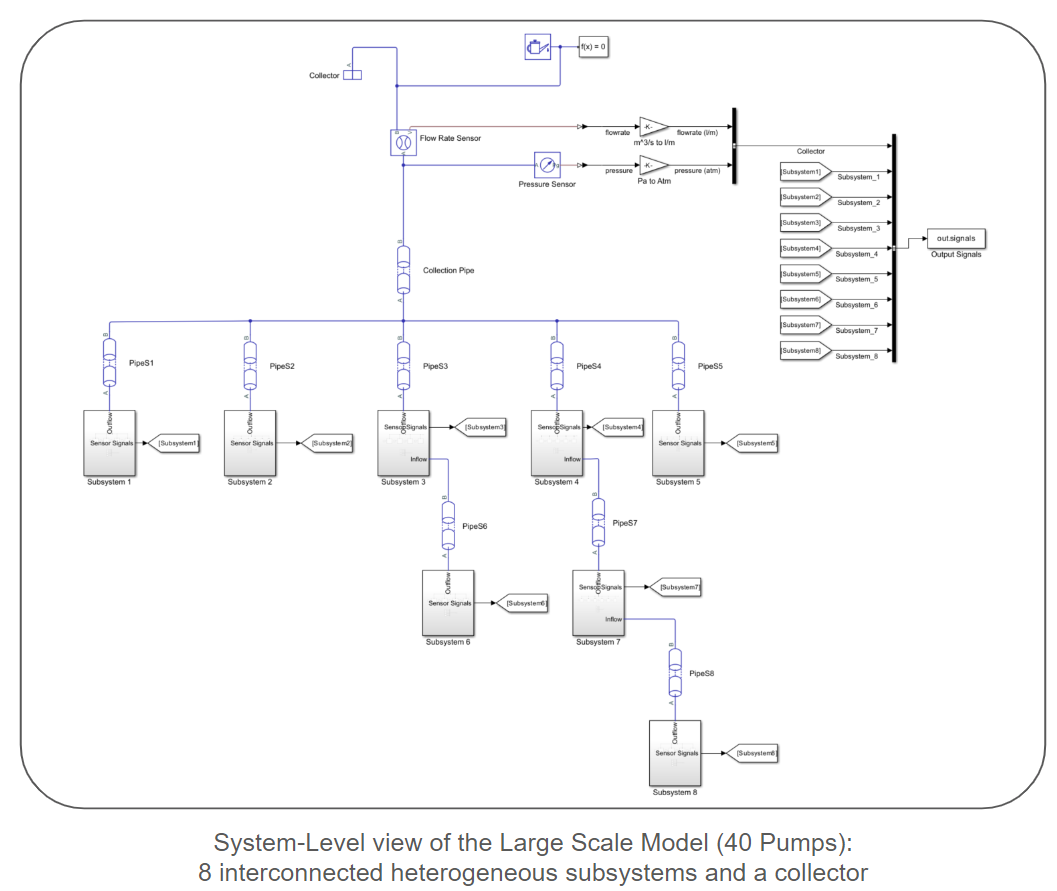

## Surrogate Model Scoping: Inputs and Outputs

Creating a surrogate model involves a series of steps. The first step is to identify the inputs and outputs of the model. These are usually determined based on the specific application of the surrogate model. Additionally, the inputs must be configurable in the physics-based model, and a method must be established to record the desired outputs after executing the physics-based simulation. The targetted workflow should inform the selection of input ranges. Ideally, the ranges are selected only large enough to accomplish the targeted workflow. Unnecessarily large bounds result in larger sampling and training times. We recommend automating the sampling processes to enhance efficiency (see provided code for examples). 

In this article, the chosen inputs for this example are source pressures, pump speeds, and the pressure at the network's collection point (sink). Below are tables listing the inputs, their selected ranges, and the outputs collected while sampling the water-pumping network models. 

## 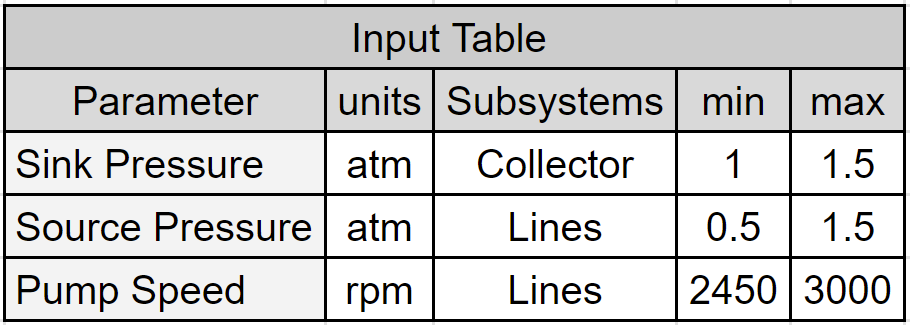

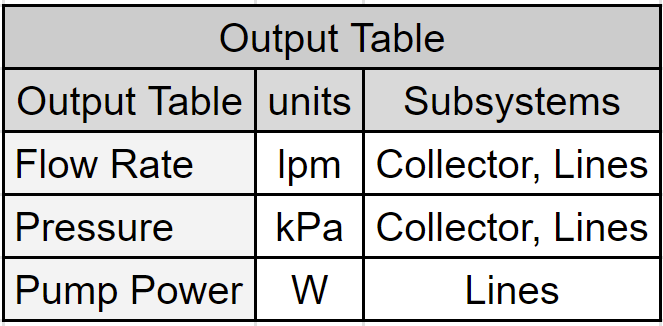

## Model Sampling

A total of 1000 and 8500 model samples were generated for the small-scaled and large-scale models, respectively. The sampling process involves the following steps for each sample:

- Randomizing inputs to the physics-based model

- Executing the physics-based model

- Allowing the model to reach a steady state

- Checking the model for errors

- Recording both inputs and outputs

CSV files store the recorded samples. The table below provides a snapshot of the first few parameters in the sample table. It's important to note that inputs are randomized independently, and each subsystem has a unique source pressure and pump speed. Adopting a sampling approach with parallel model instances will reduce the time required to obtain a sample set. The "score" columns confirm that the system reached a steady state and are not training parameters.

dataTable = readtable('.\Data Sets\small\complete_smallWaterPumpingNetwork.csv');
disp(dataTable(2:6,:))

    sim_time    output_collector_flowrate__l_m_    score_output_collector_flowrate__l_m_    output_1_Line1_flowrate__l_m_    score_output_1_Line1_flowrate__l_m_    output_1_Line1_pressure__kPa_    score_output_1_Line1_pressure__kPa_    output_1_Line1_power__W_    score_output_1_Line1_power__W_    output_1_Line2_flowrate__l_m_    score_output_1_Line2_flowrate__l_m_    output_1_Line2_pressure__kPa_    score_output_1_Line2_pressure__kPa_    output_1_Line2_power__W_    score_output_1_Line2_power__W_    output_1_Line3_flowrate__l_m_    score_output_1_Line3_flowrate__l_m_    output_1_Line3_pressure__kPa_    score_output_1_Line3_pressure__kPa_    output_1_Line3_power_

The figure below illustrates the wide range of values of the collector flow rate found in the collected samples. 

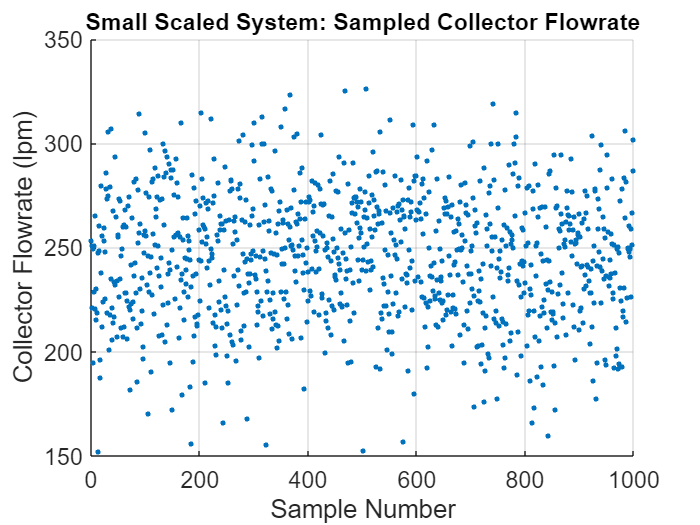

scatter(1:1000,(table2array(dataTable(:,"output_collector_flowrate__l_m_"))),10,'filled')
ylabel('Collector Flowrate (lpm)','FontSize',14);
xlabel('Sample Number','FontSize',14);
title('Small Scaled System: Sampled Collector Flowrate','FontSize',14);
grid on
hAx = gca;
hAx.XAxis.FontSize = 14;
hAx.YAxis.FontSize = 14;

## Surrogate Model Generation and Deployment

We trained a surrogate model with the collected sampled set. This article uses MATLAB's Deep Learning Toolbox [1] to train a Multilayer Perceptron (MLP) [2, 3]. The sampling set is divided into a training set (80% of samples), a validation set (10% of samples), and a testing set (10% of samples) (refer to [4] for definitions of the different sets). MAT files store the model's parameters and structure. The provided P-code files execute inference by reconstructing surrogate models with the stored parameters and structure. The P-code functions return the MLP's prediction of system behavior (outputs) as a function of its inputs.

Click on the button below to run a randomly selected scenario.

 

if ~exist('parameter_small_mlp','var')
    addpath("./Surrogate Models")
    load('./Surrogate Models/small_model.mat');
    load('./Surrogate Models/large_model.mat');
    disp("MLP parameters loaded.")
end

x = rand(9,1).*[0.5;550;1;550;1;550;1;550;1] + [1;2450;0.5;2450;0.5;2450;0.5;2450;0.5];
ypred_mlp = small_scale_inference(x, parameter_small_mlp);

disp('Inputs:')

Inputs:


disp(['Pressure Collector (atm): ' num2str(x(1),'%.2f')])

Pressure Collector (atm): 1.36


disp(['Pump 1-4 Speeds (rpm): ' num2str(x(2),'%.2f') ', '...
                                    num2str(x(4),'%.2f') ', '...
                                    num2str(x(6),'%.2f') ', '...
                                    num2str(x(8),'%.2f')])

Pump 1-4 Speeds (rpm): 2525.62, 2676.19, 2628.75, 2671.49


disp(['Source 1-4 Pressures (atm): ' num2str(x(3),'%.2f') ', '...
                                    num2str(x(5),'%.2f') ', '...
                                    num2str(x(7),'%.2f') ', '...
                                    num2str(x(9),'%.2f')])

Source 1-4 Pressures (atm): 0.60, 0.76, 0.71, 0.82


disp('Outputs:')

Outputs:


disp(['Collector Flowrate (lpm): ' num2str(ypred_mlp(1),'%.2f') ])

Collector Flowrate (lpm): 177.48


disp(['Line 1-4 Flowrates (lpm): ' num2str(ypred_mlp(2),'%.2f') ', '...
                                    num2str(ypred_mlp(5),'%.2f') ', '...
                                    num2str(ypred_mlp(8),'%.2f') ', '...
                                    num2str(ypred_mlp(11),'%.2f')])

Line 1-4 Flowrates (lpm): 34.55, 54.46, 36.71, 51.39


disp(['Line 1-4 Pressures (kPa): ' num2str(ypred_mlp(3),'%.2f') ', '...
                                    num2str(ypred_mlp(6),'%.2f') ', '...
                                    num2str(ypred_mlp(9),'%.2f') ', '...
                                    num2str(ypred_mlp(12),'%.2f')])

Line 1-4 Pressures (kPa): 284.66, 274.94, 313.97, 290.64


disp(['Line 1-4 Pump Power (W): ' num2str(-1*ypred_mlp(4),'%.2f') ', '...
                                    num2str(-1*ypred_mlp(7),'%.2f') ', '...
                                    num2str(-1*ypred_mlp(10),'%.2f') ', '...
                                    num2str(-1*ypred_mlp(13),'%.2f')])

Line 1-4 Pump Power (W): 366.11, 473.99, 404.28, 464.75


## Surrogate Model Evaluation

### Prediction Errors

The figures below plot the surrogate predictions against the physics-based outputs for the training, validation, and testing sets. MLPs tend to be overfitted, resulting in smaller errors for the training set. Therefore, the metrics from the validation and testing sets provide a more accurate indication of errors when predicting configurations not present in the sampled set. 

The tables and figures show the surrogate's prediction error metrics (formula given below). Note that prediction errors are only a tiny fraction of the predicted values and may even be negligible in most practical applications.


$$\text{Surrogate Precent Error} = \text{Surrogate Prediction - Simulation Value}$$


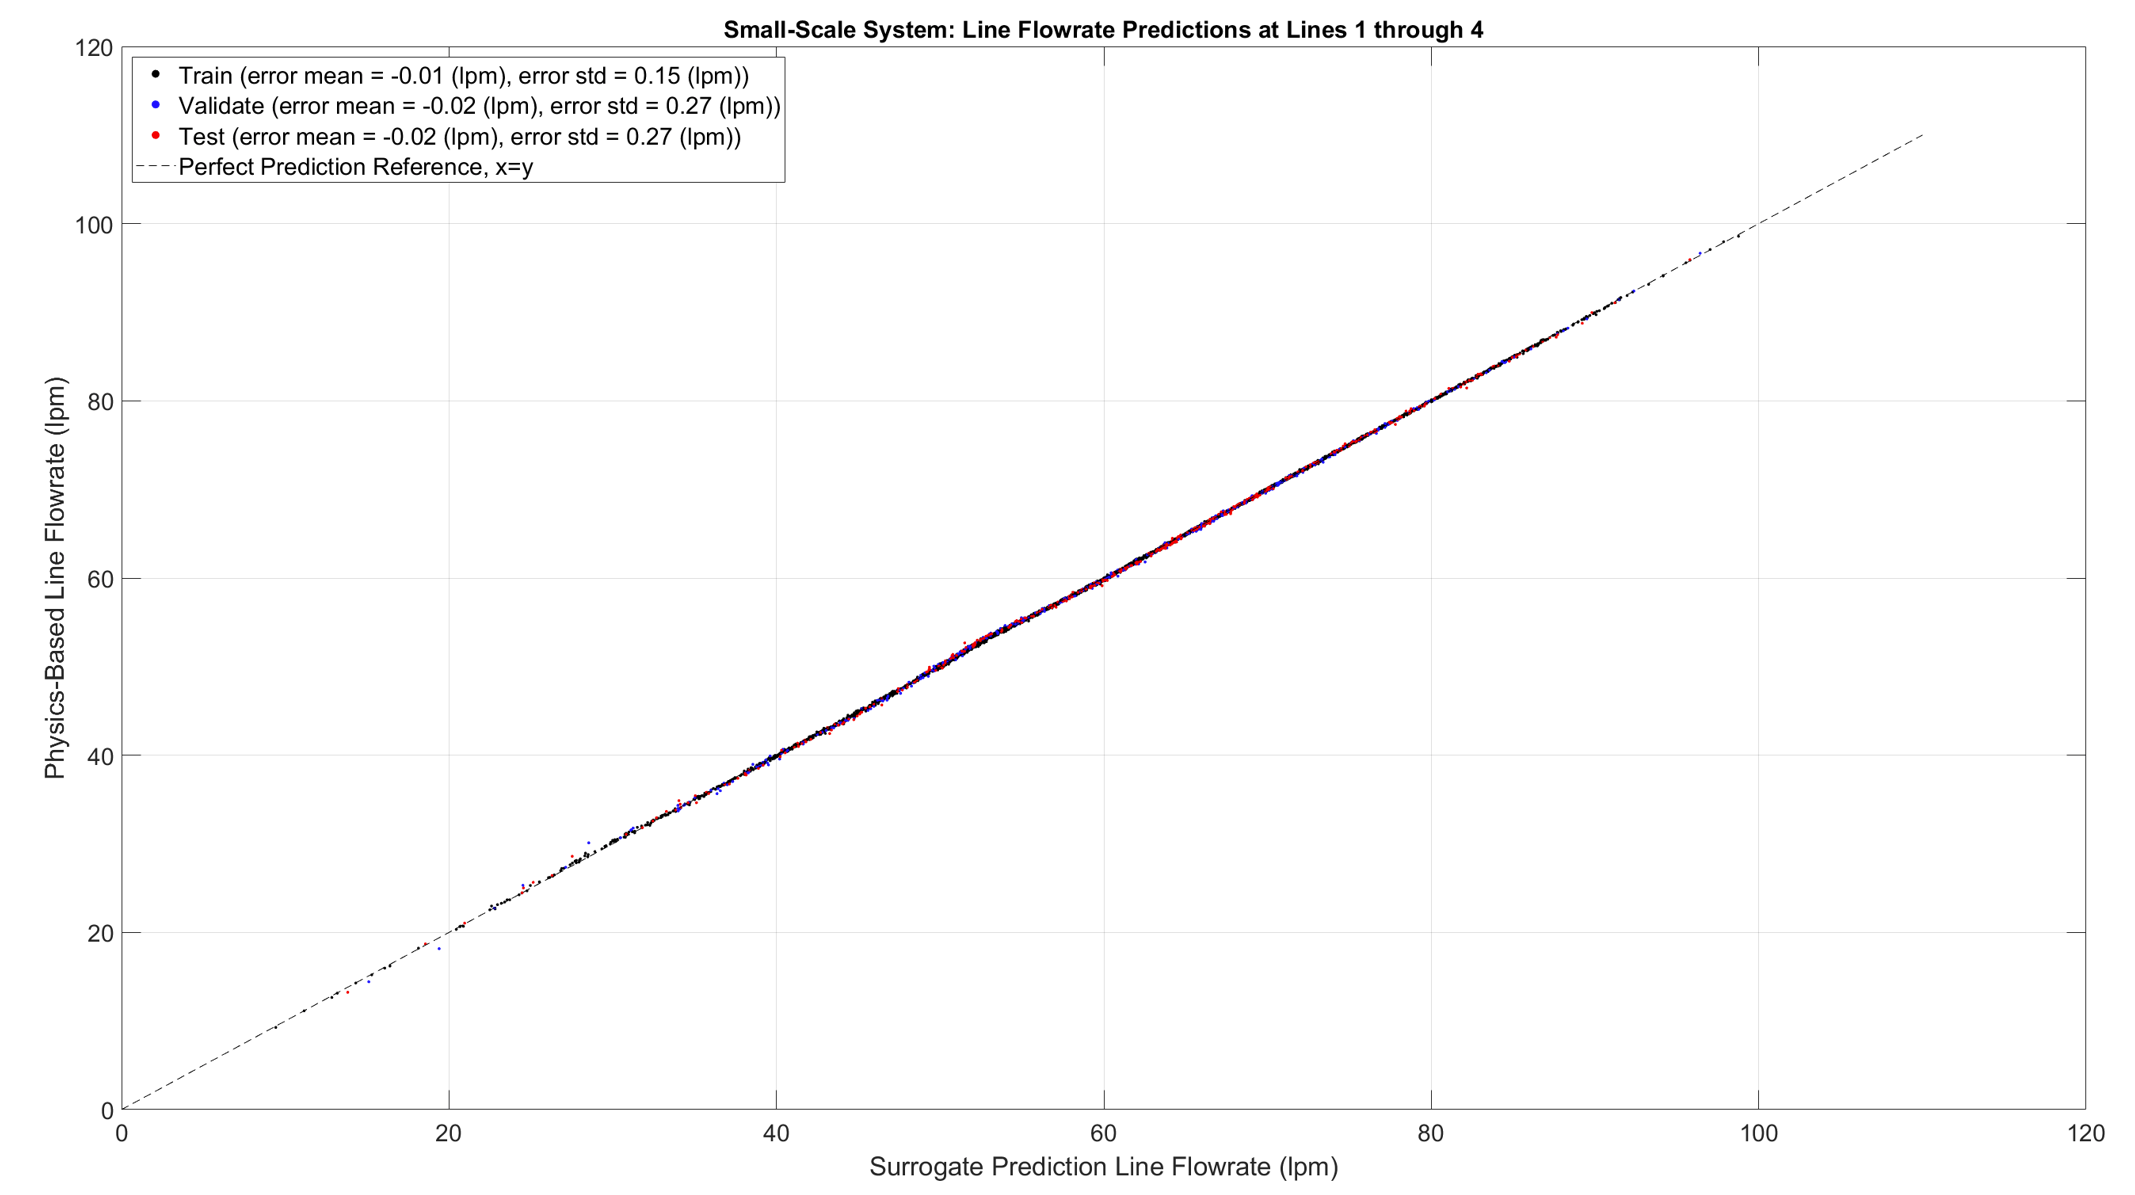

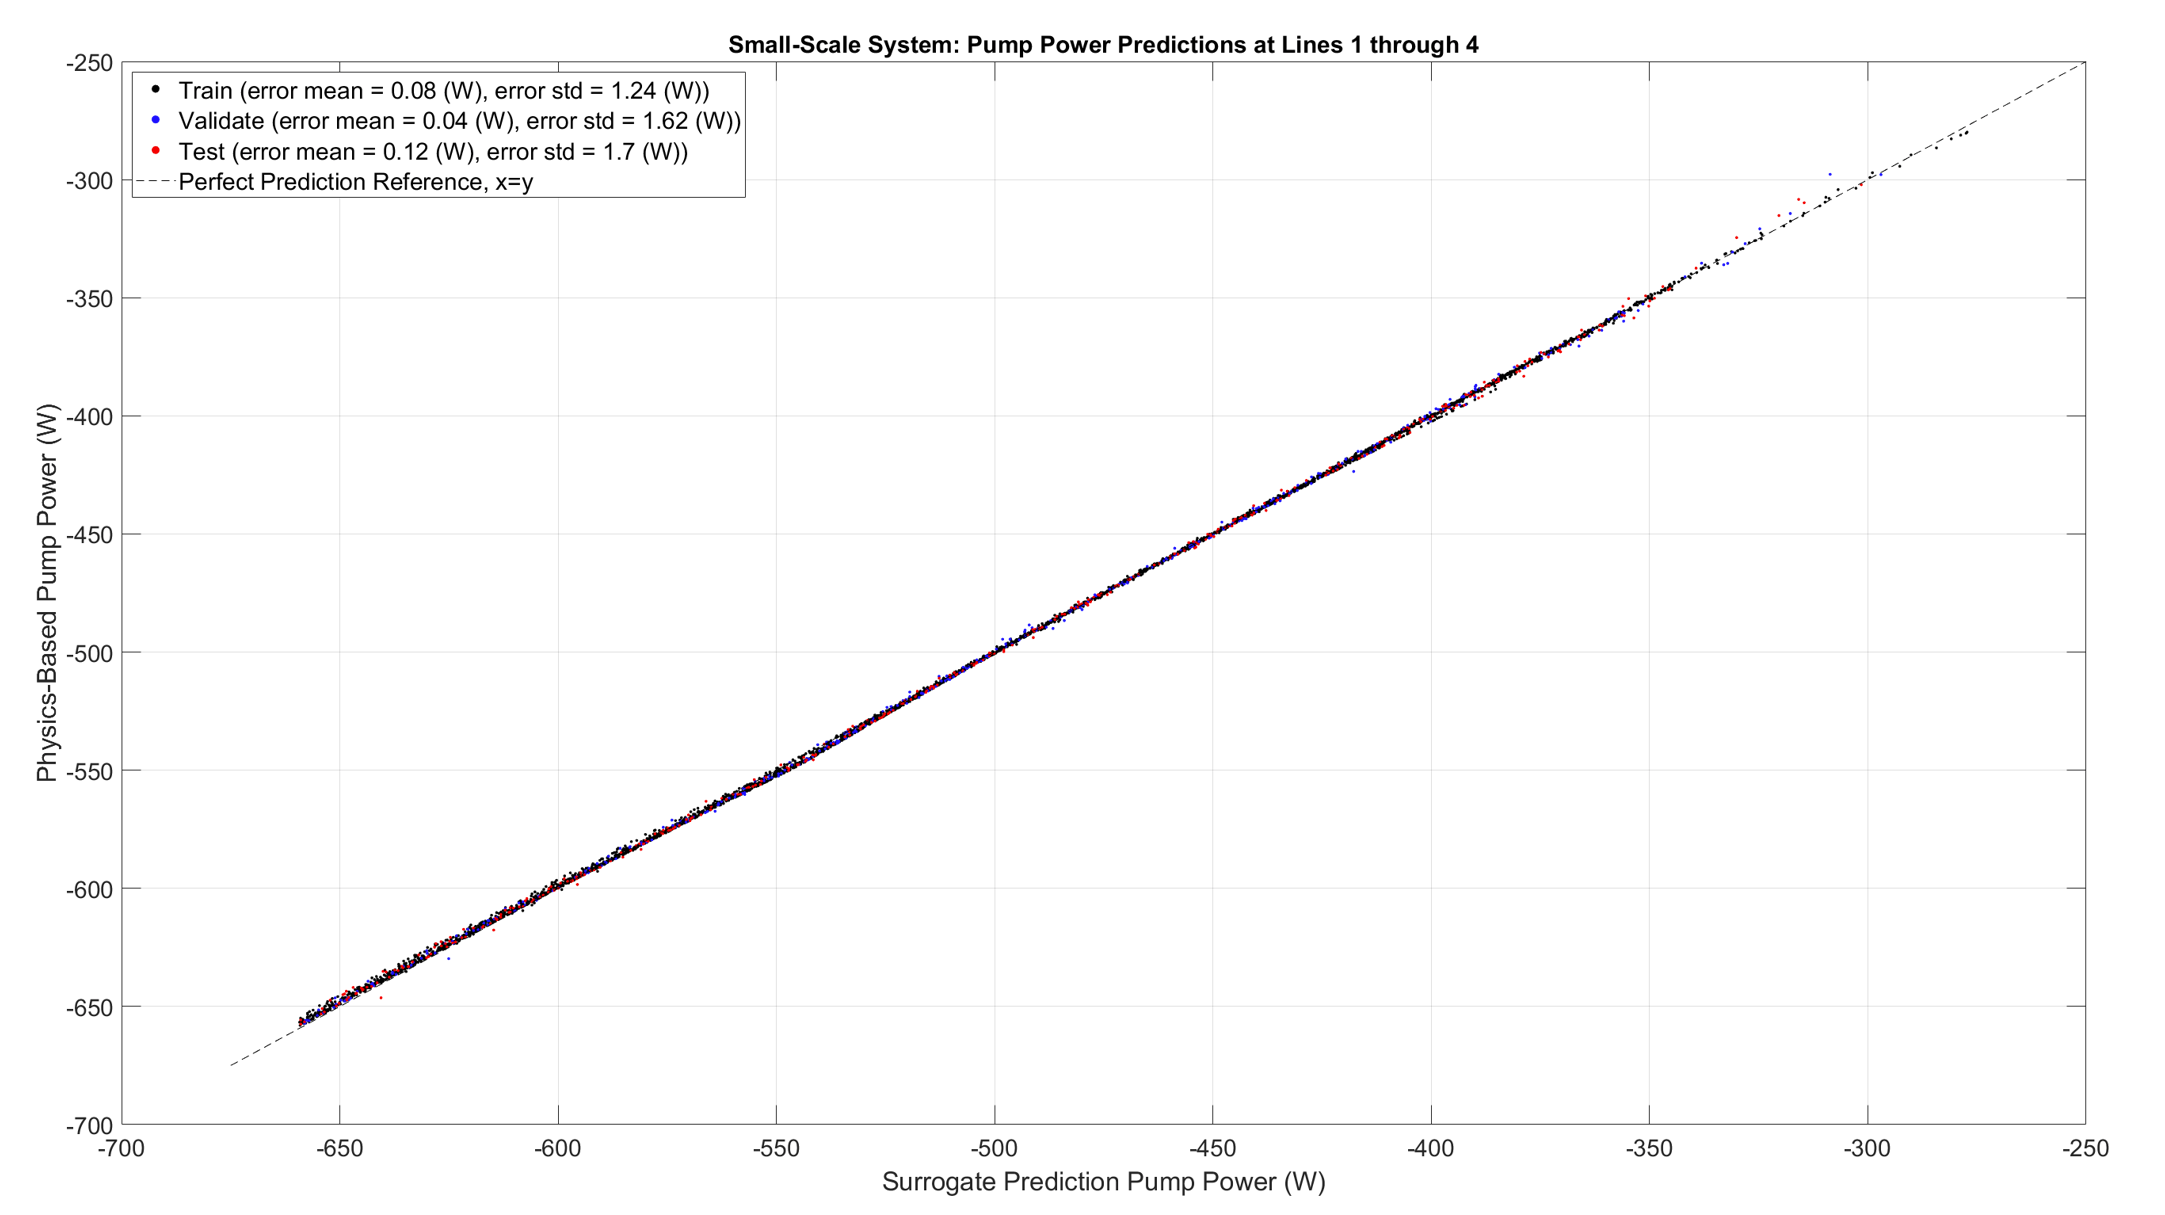

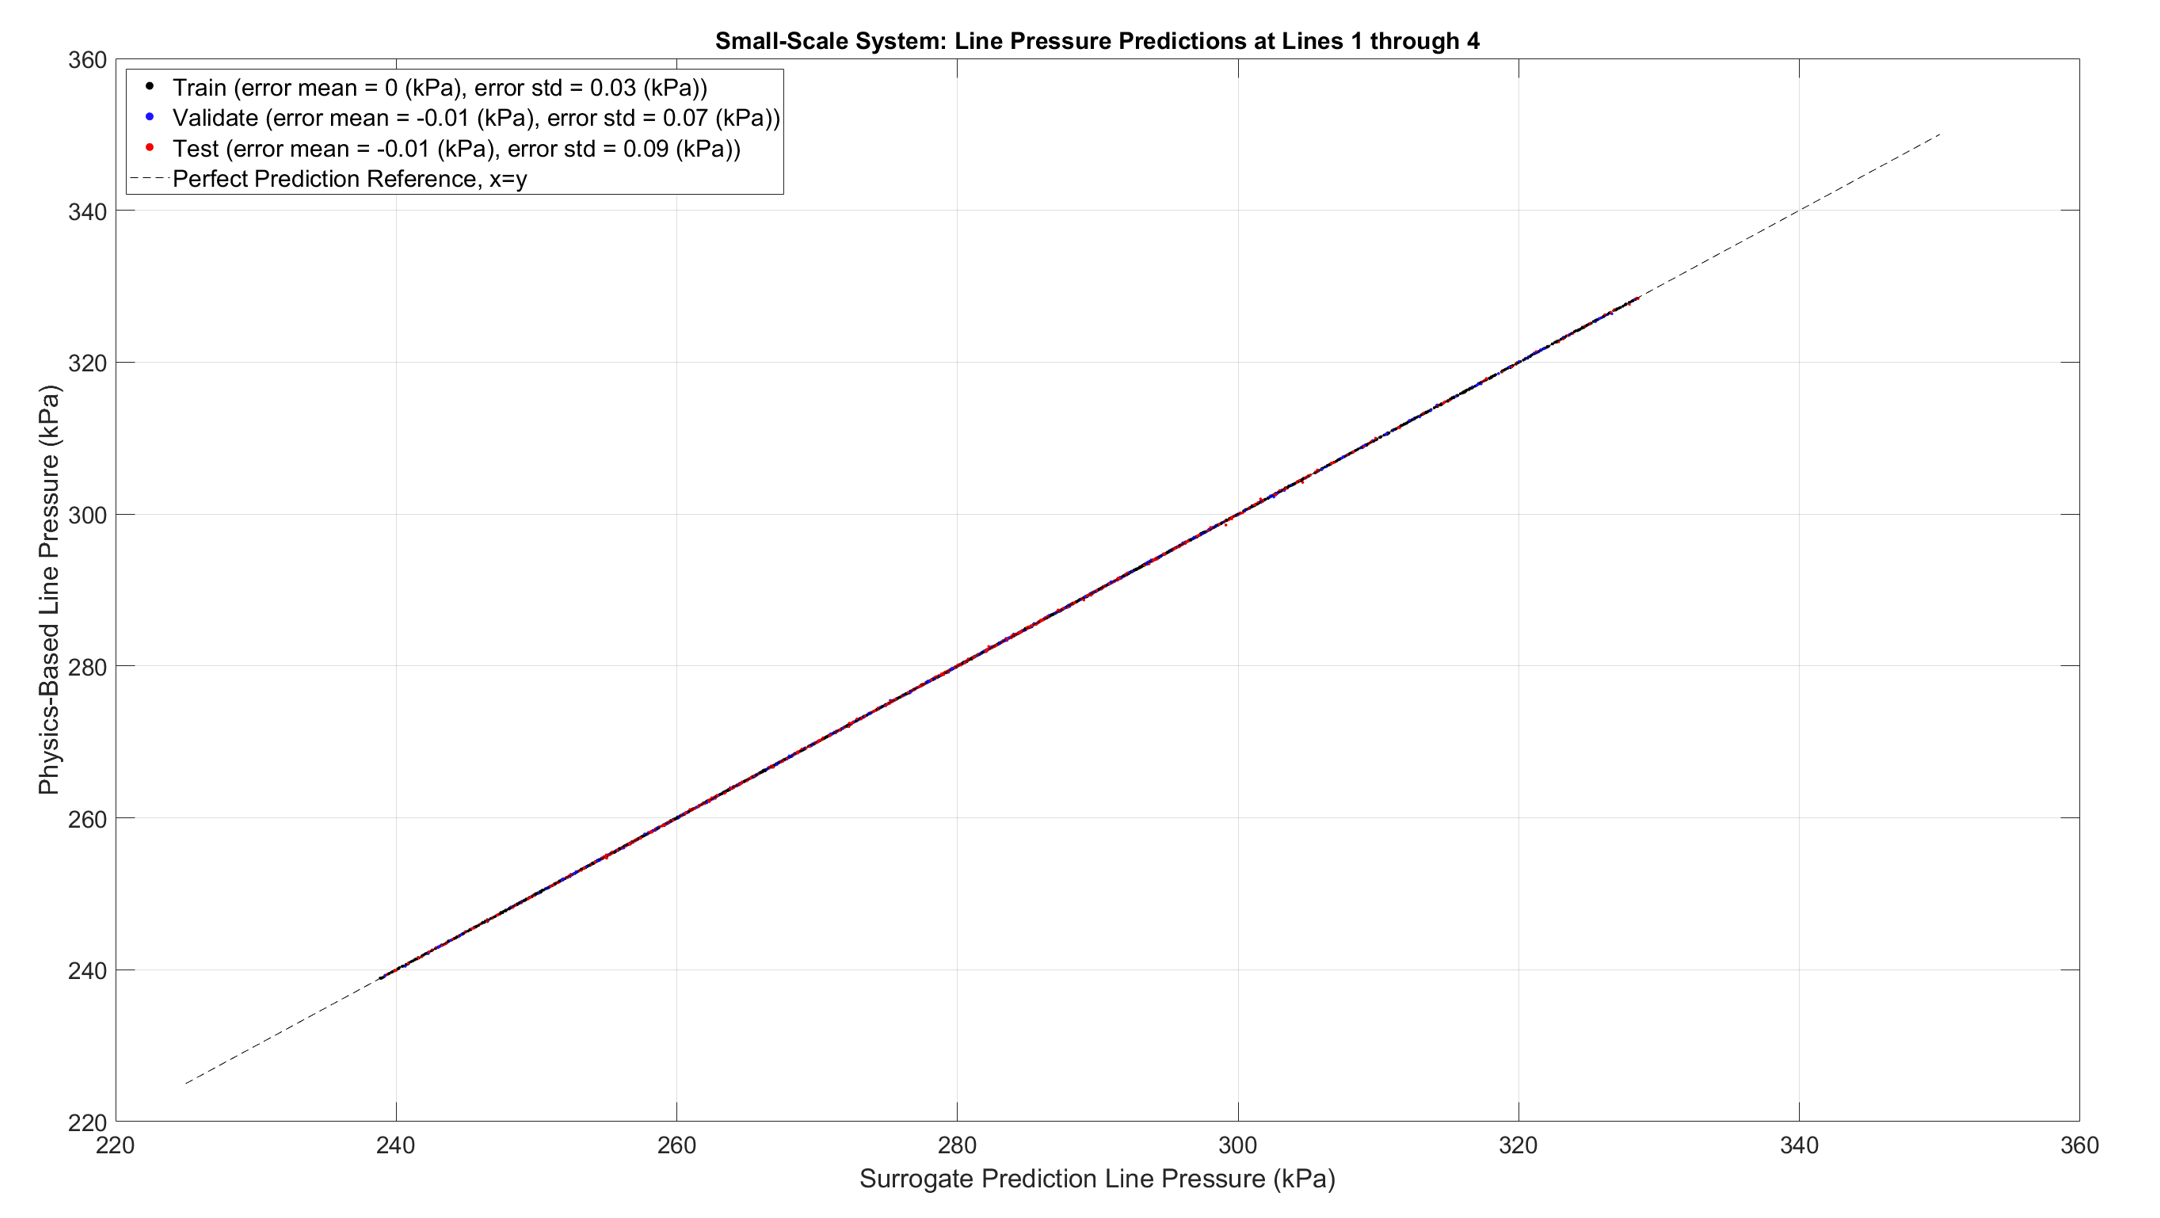

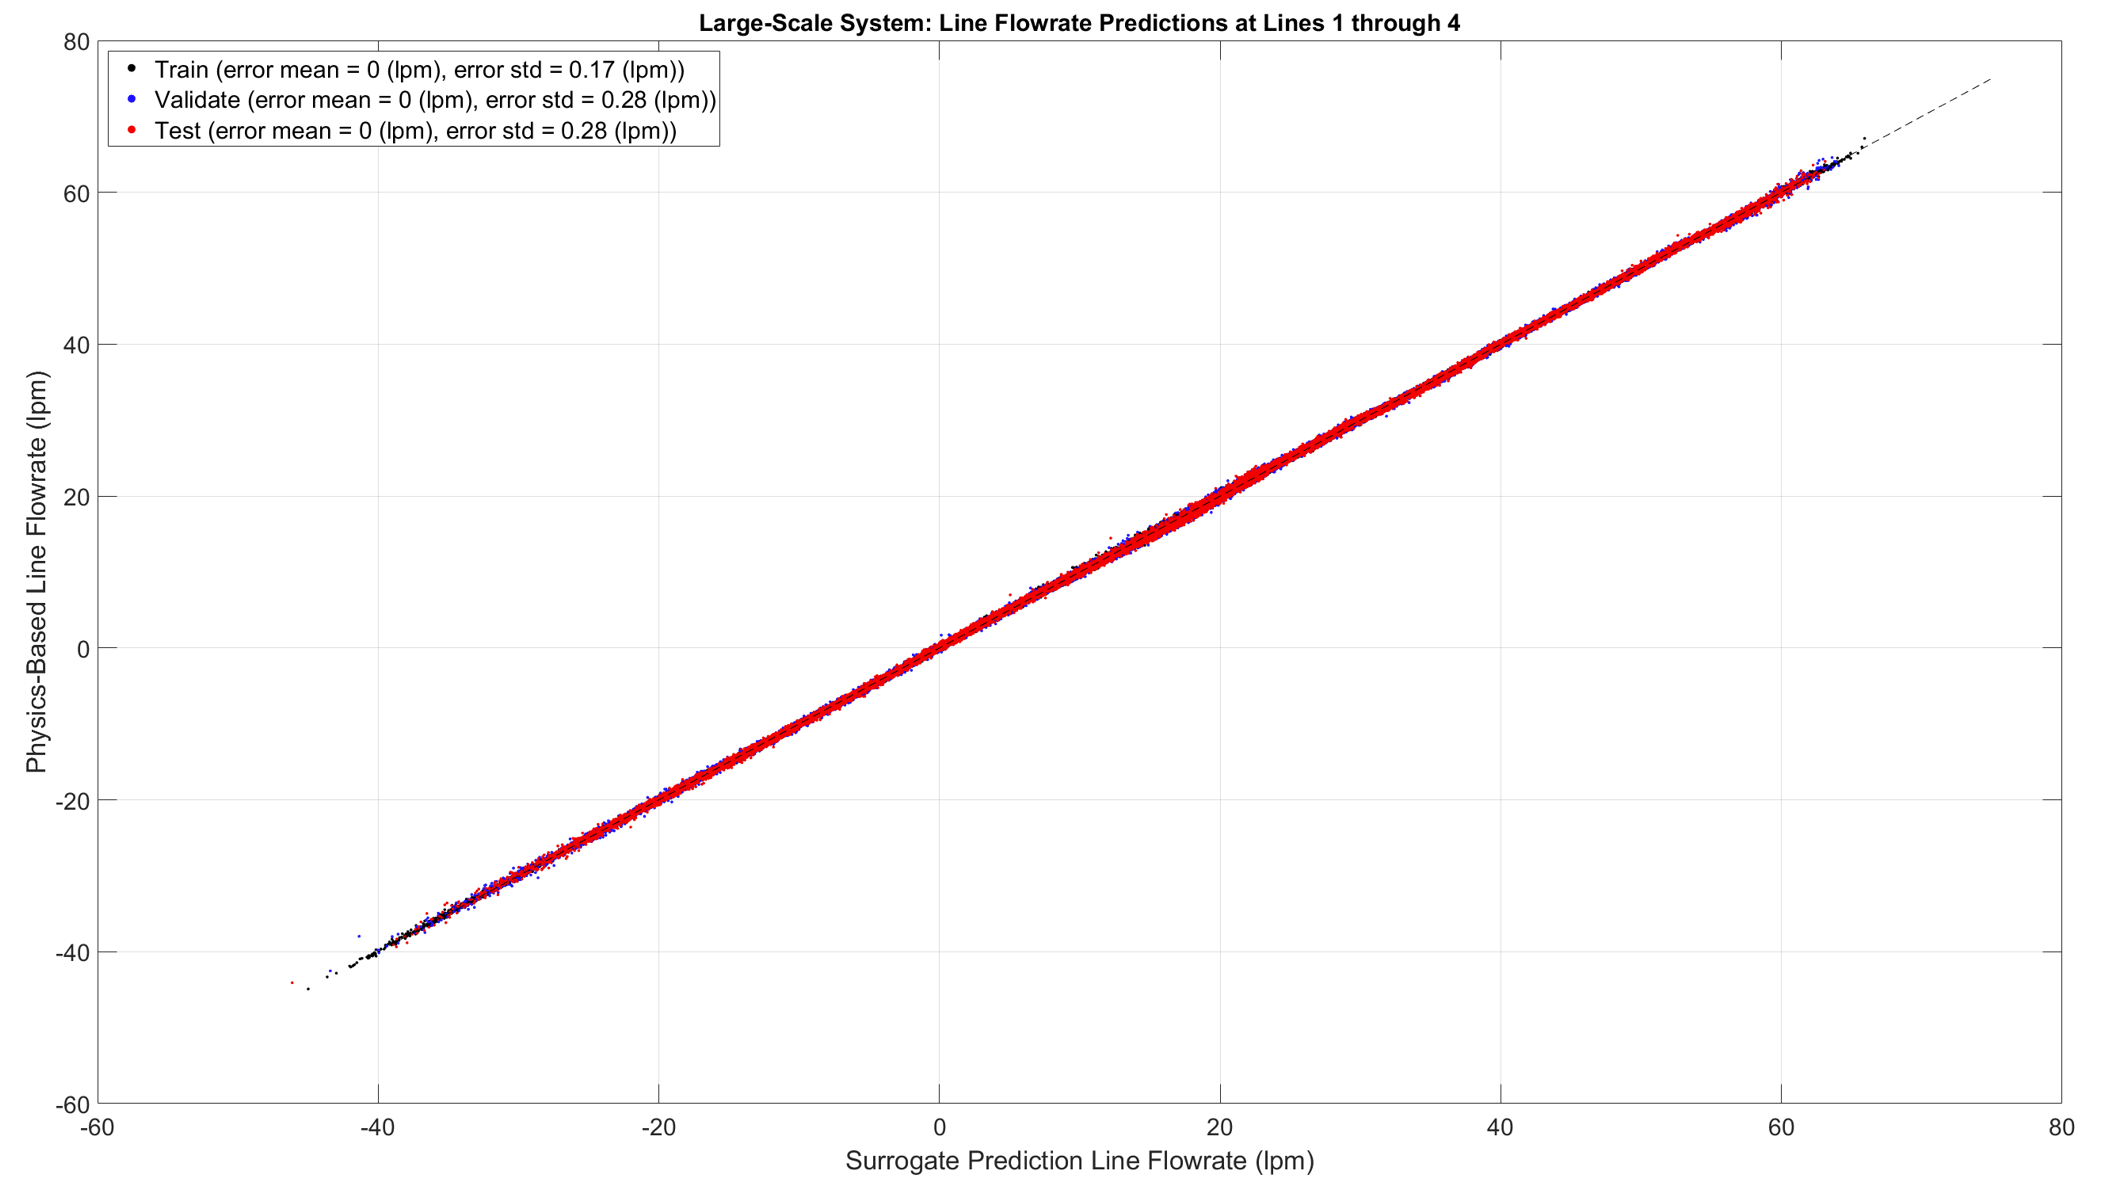

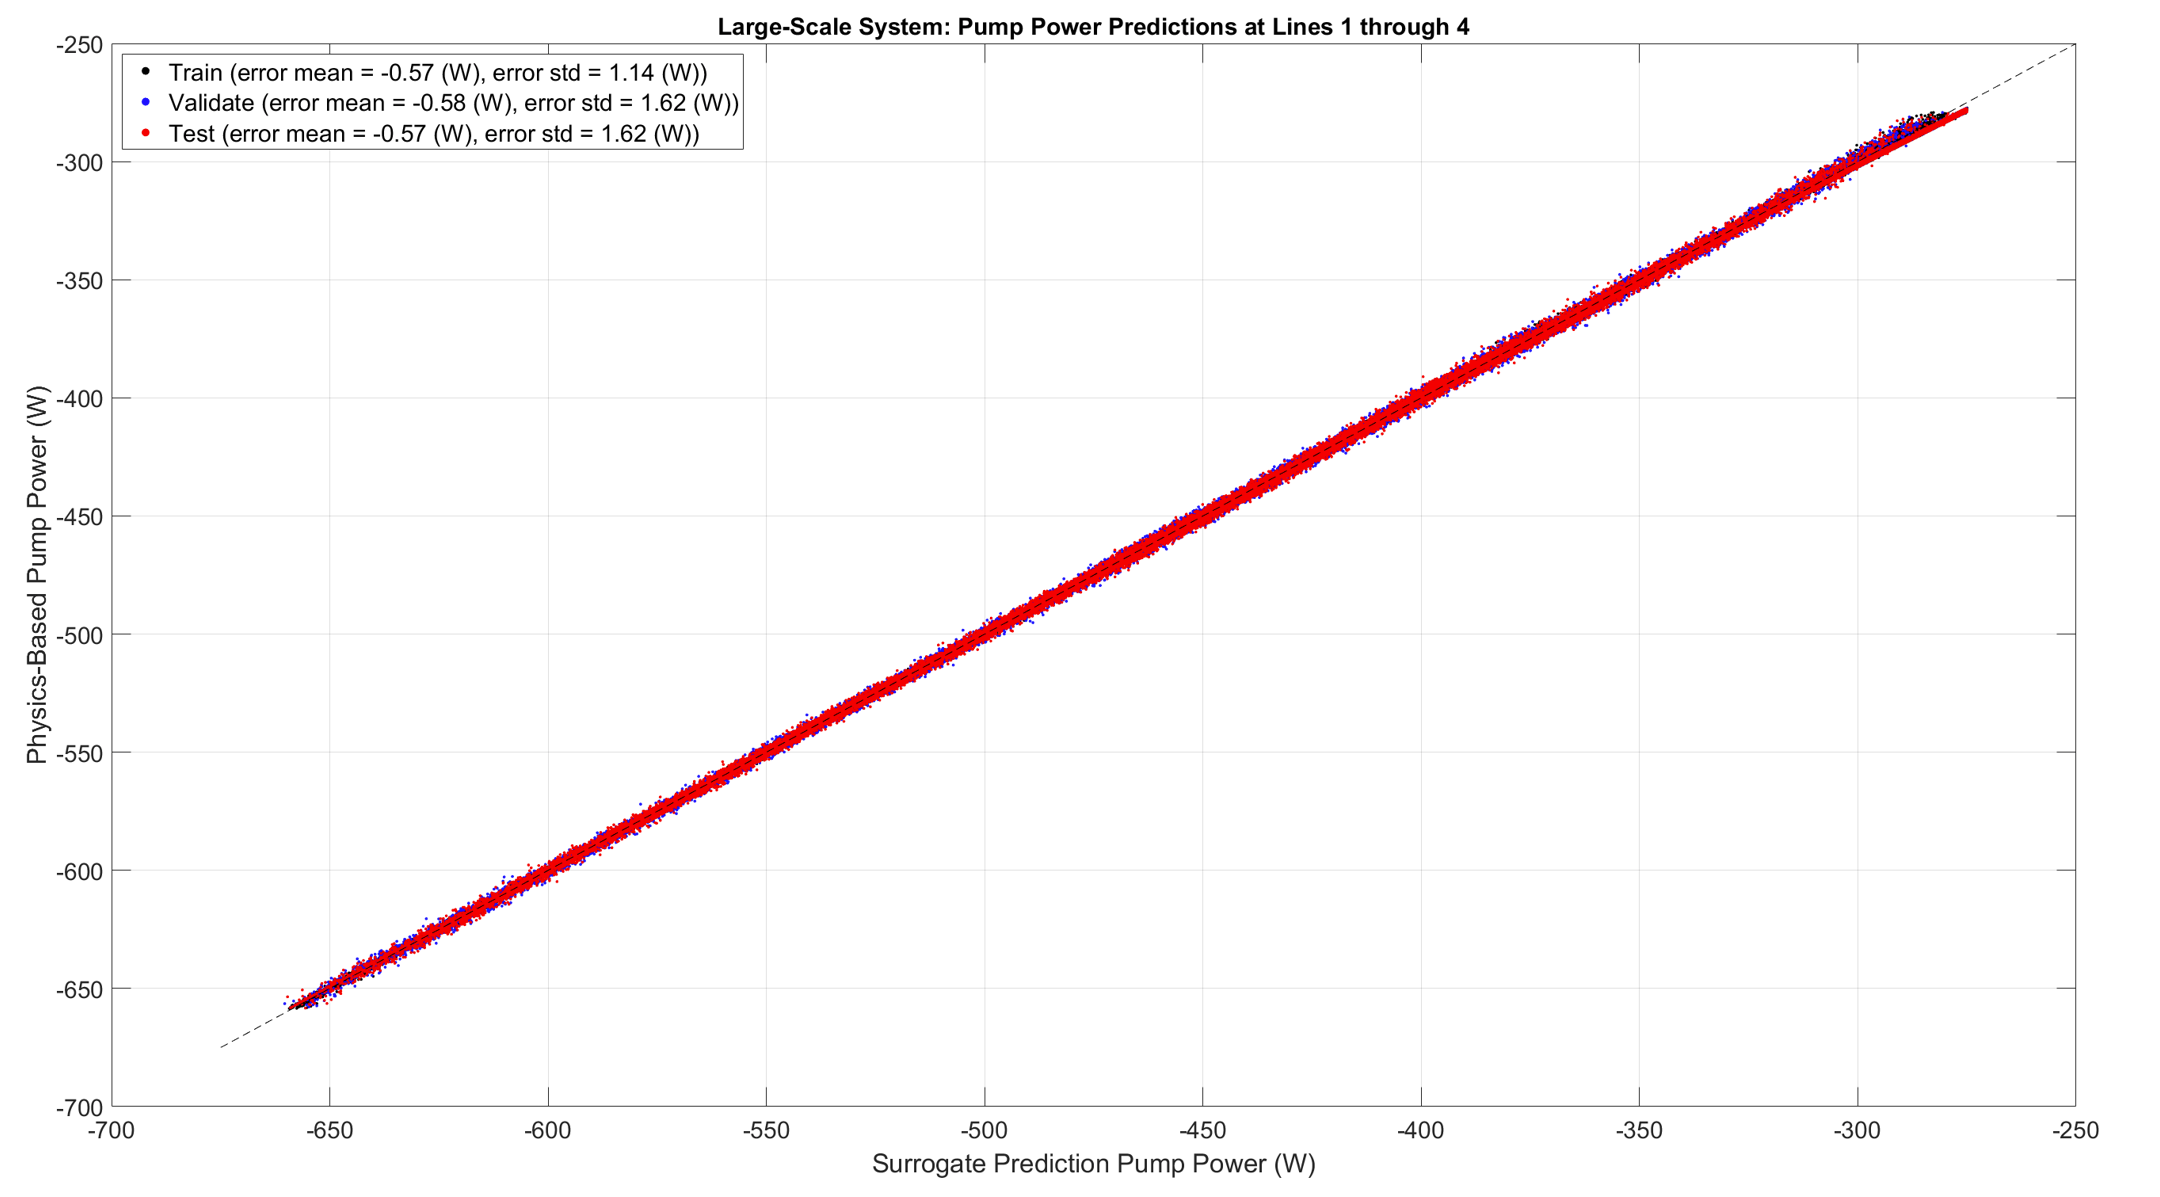

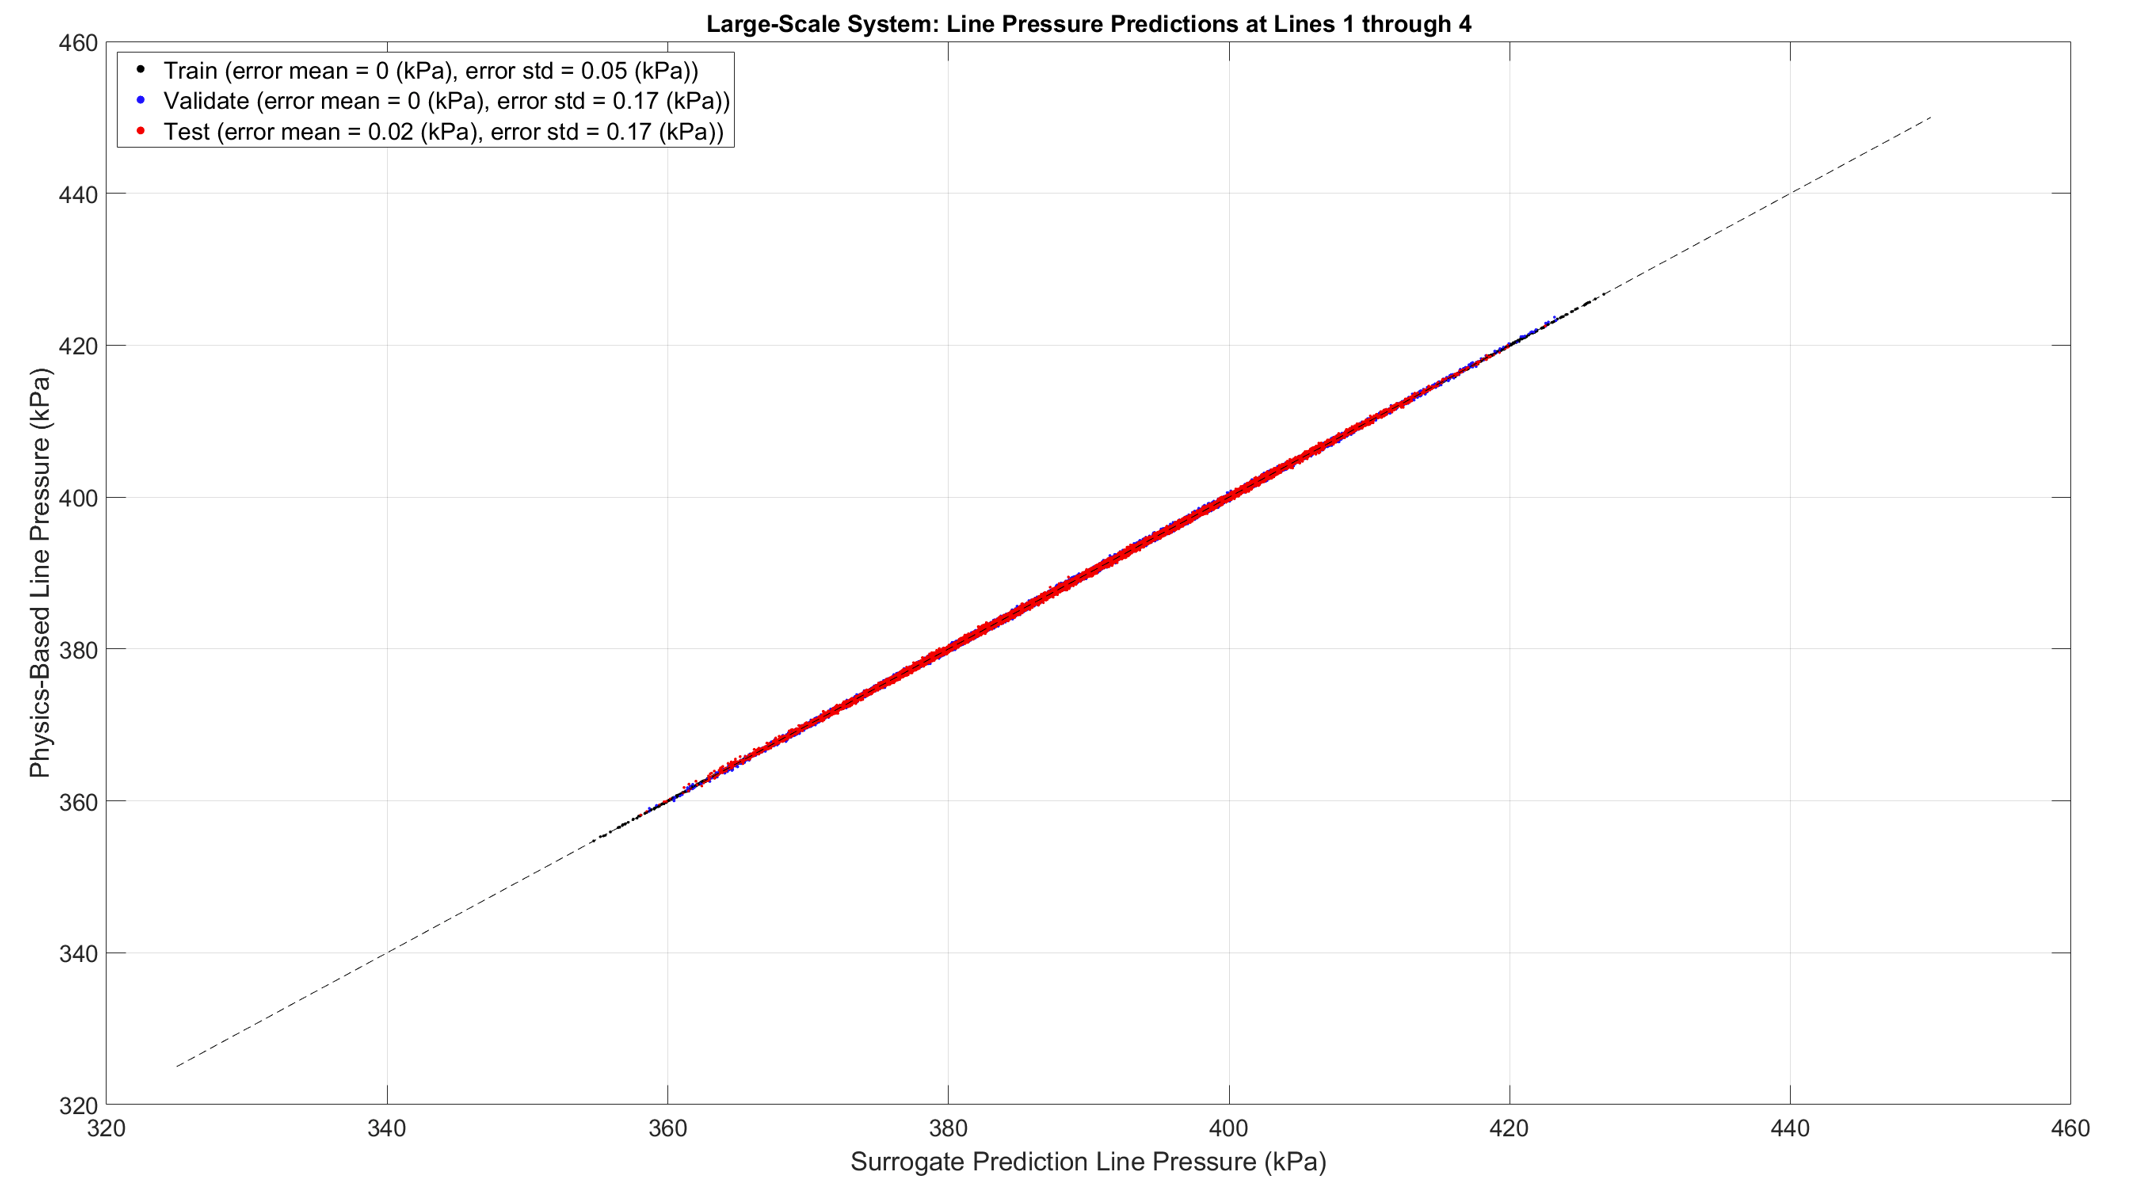

### Evaluation Time

Surrogate model inference occurs much quicker than executing a physics-based model. One can expect speed-ups of multiple orders of magnitude. Recall that inferencing a surrogate model is mostly a series of additions, multiplications, and simple activation functions. There are no complex physics equations to solve or keep track of. The presented surrogate will be even quicker with more efficient deployments. 

With the slider bar below, select the number of samples to test with and run a speed time evaluation. 

if ~exist('parameter_small_mlp','var')
    addpath("./Surrogate Models")
    load('./Surrogate Models/small_model.mat');
    load('./Surrogate Models/large_model.mat');
    disp("MLP parameters loaded.")
end

%Collection Parameters
sampled_name_list = ["collector_pressure"]; % parameter ID
lower_limit = [1]; % lower limit for sampling 
upper_limit = [1.5]; % upper limit for sampling

%Line 1-40 Parameters
for idx = 1:40
    sampled_name_list(end+1) = strcat("pump_speed_", int2str(idx));
    lower_limit(end+1) = 2450;
    upper_limit(end+1) = 3000;
    sampled_name_list(end+1) = strcat("source_pressure_", int2str(idx));
    lower_limit(end+1) = 0.5;
    upper_limit(end+1) = 1.5;
end

% Generate Random Samples for Small-Scale
numSamples = 6090;
X = rand(9,numSamples).*(upper_limit(1:9)' - lower_limit(1:9)') + lower_limit(1:9)';

wall_time = 0;
% Evaluation Each in Series
for idx = 1:numSamples
tic
small_scale_inference(X(:,idx),parameter_small_mlp);
wall_time = toc + wall_time;
end
disp(['Average Small-Scale Single Evaluation Time (s): ' num2str(wall_time/numSamples)]);

Average Small-Scale Single Evaluation Time (s): 0.0029116



tic
small_scale_inference(X,parameter_small_mlp);
wall_time = toc;
disp(['Small-Scale Evaluation Time for a Batch of '...
      num2str(numSamples) ' samples (s): ' num2str(wall_time/numSamples)]);

Small-Scale Evaluation Time for a Batch of 6090 samples (s): 4.3191e-06



% Generate Random Samples for Large-Scale
X = rand(81,numSamples).*(upper_limit(1:81)' - lower_limit(1:81)') + lower_limit(1:81)';

wall_time = 0;
% Evaluation Each in Series
for idx = 1:numSamples
tic
large_scale_inference(X(:,idx),parameter_large_mlp);
wall_time = toc + wall_time;
end
disp(['Average Large-Scale Single Evaluation Time (s): ' num2str(wall_time/numSamples)]);

Average Large-Scale Single Evaluation Time (s): 0.0035685



tic
large_scale_inference(X,parameter_large_mlp);
wall_time = toc;
disp(['Large-Scale Evaluation Time for a Batch of '...
      num2str(numSamples) ' samples (s): ' num2str(wall_time/numSamples)]);

Large-Scale Evaluation Time for a Batch of 6090 samples (s): 1.0352e-05


## Summary

The tables below (the same ones shown in High-Level Highlights) offer a performance comparison between the surrogate model and the physics-based models. Surrogate models significantly reduce execution time by orders of magnitude while introducing only minor errors into the system's predictions. Further reduction in surrogate model execution time is achievable with more time-efficient deployments. Notably, the reduction in execution time is more pronounced in the large-scale model.

In essence, the outlined approach transforms the role of physics-based simulations from analysis engines to data generators. As demonstrated in other articles, well-fitted surrogate models have the potential to replace physics-based simulations in most workflows and even make some previously infeasible ones feasible. One can effectively remove the physics-based model bottleneck in optimization and analysis use cases by investing time and computational resources upfront in sampling and surrogate model generation. We continue down this path in Surrogate Model-Based Optimization, where we introduce a lightning-fast surrogate model optimization framework.

## References

[1] [MATLAB’s Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html)

[2] [MLP Crash Course](https://machinelearningmastery.com/neural-networks-crash-course/)

[3] [MLP Basics and Structure](https://towardsdatascience.com/multilayer-perceptron-explained-with-a-real-life-example-and-python-code-sentiment-analysis-cb408ee93141)

[4] [Definitions of Datasets](https://machinelearningmastery.com/difference-test-validation-datasets/)